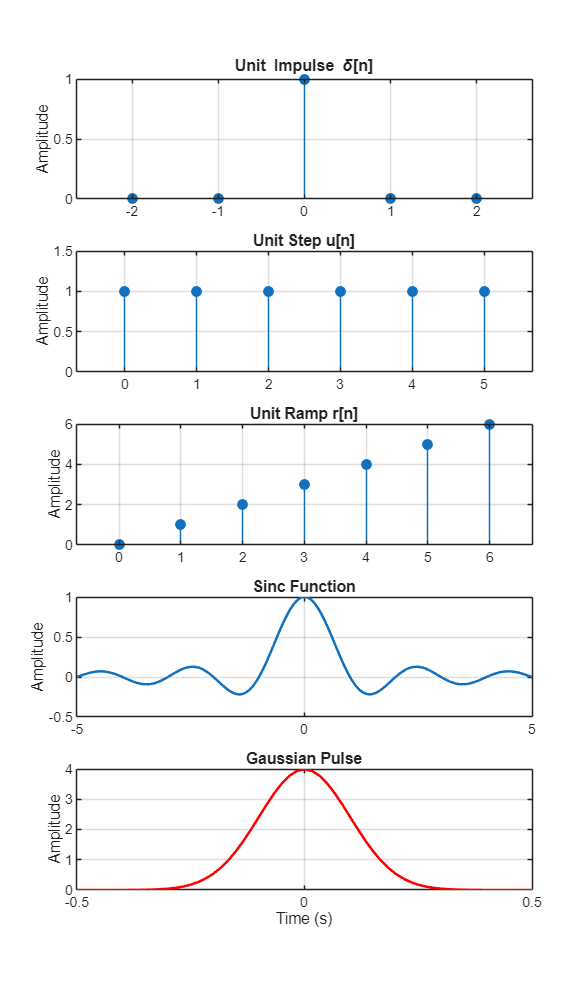

clc; close all; clear all;

% Set a custom figure size [left, bottom, width, height]
% We make the height (800) much larger than the width (500)
figure('Name', 'Elementary Signals', 'Position', [100, 100, 500, 850]);

% --- 1. Unit Impulse ---
subplot(5, 1, 1);
n_imp = -2:2;
y_imp = [0 0 1 0 0];
stem(n_imp, y_imp, 'filled');
title('Unit Impulse \delta[n]');
ylabel('Amplitude');
grid on;

% --- 2. Unit Step ---
subplot(5, 1, 2);
n_val = 6; % From your image
t_step = 0:n_val-1;
y_step = ones(1, n_val);
stem(t_step, y_step, 'filled');
title('Unit Step u[n]');
ylabel('Amplitude');
ylim([0 1.5]); % Adds breathing room at the top
grid on;

% --- 3. Unit Ramp ---
subplot(5, 1, 3);
t_ramp = 0:n_val;
stem(t_ramp, t_ramp, 'filled');
title('Unit Ramp r[n]');
ylabel('Amplitude');
grid on;

% --- 4. Sinc Function ---
subplot(5, 1, 4);
t_sinc = linspace(-5, 5, 200);
plot(t_sinc, sinc(t_sinc), 'LineWidth', 1.5);
title('Sinc Function');
ylabel('Amplitude');
grid on;

% --- 5. Gaussian Pulse ---
subplot(5, 1, 5);
Fs = 60;
t_g = -0.5:1/Fs:0.5;
x_g = 1/(sqrt(2*pi*0.01))*(exp(-t_g.^2/(2*0.01)));
plot(t_g, x_g, 'r', 'LineWidth', 1.5);
title('Gaussian Pulse');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;